ptCloudWithMarker = stlread("WithMark.stl");
ptCloudWithMark = pointCloud(ptCloudWithMarker.Points*1000)

ptCloudWithMark =   pointCloud のプロパティ:

     Location: [60754×3 double]
        Count: 60754
      XLimits: [-56.3963 64.3720]
      YLimits: [-21.4013 119.3711]
      ZLimits: [-128.3727 367.0965]
        Color: []
       Normal: []
    Intensity: []


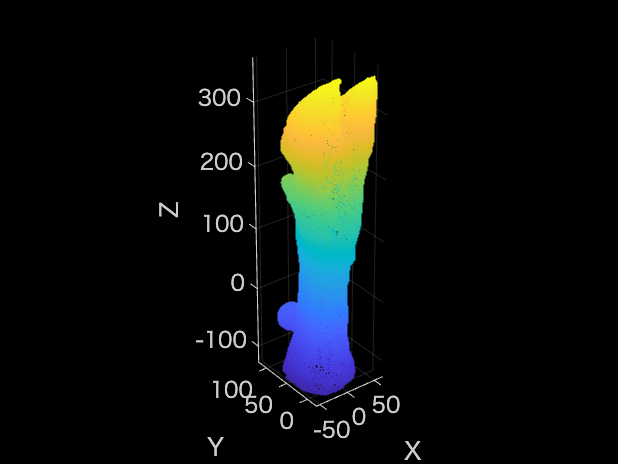

pcshowWithAxes(ptCloudWithMark)

ax = gca;
roi = images.roi.Cuboid(ax, 'Rotatable', 'all', 'Color', 'r');
draw(roi);

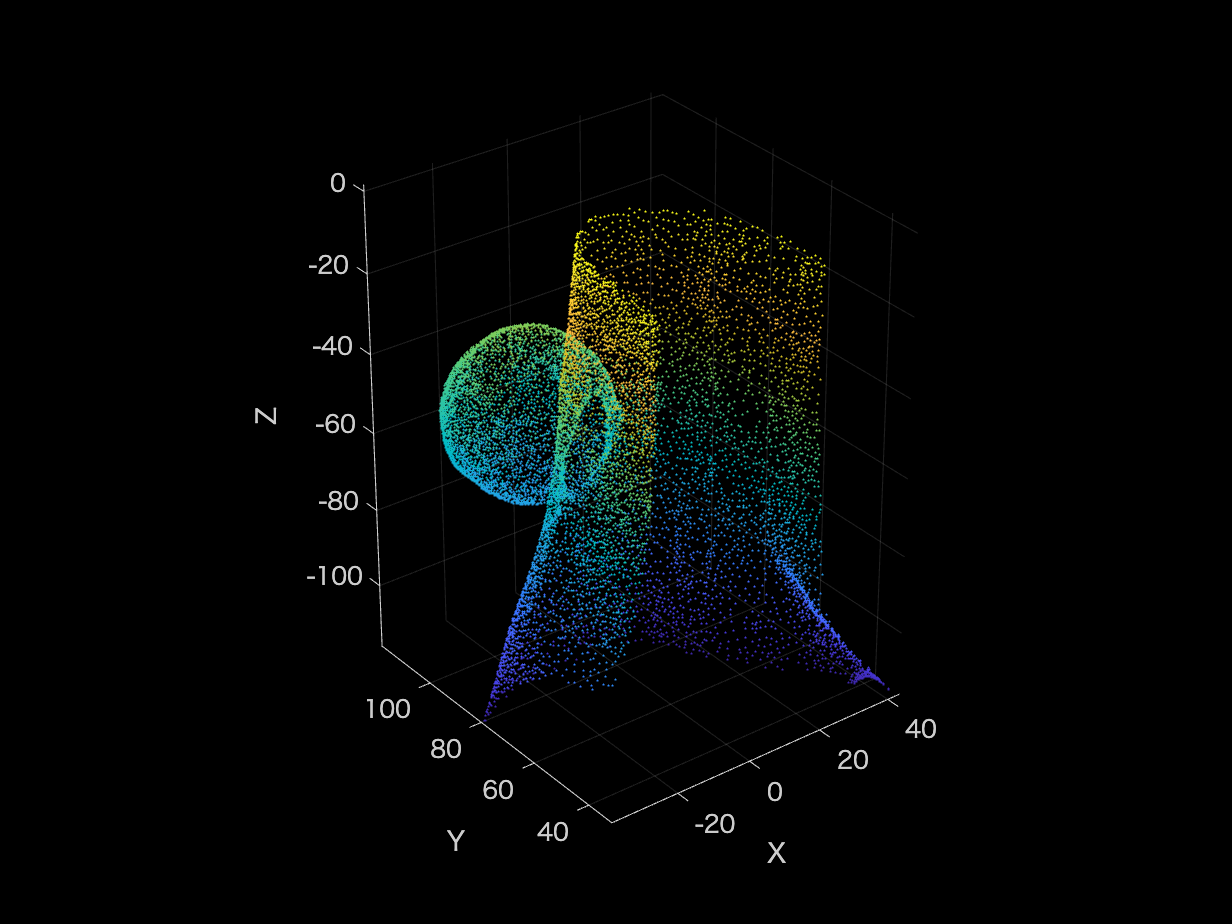

xmin = roi.Position(1);
ymin = roi.Position(2);
zmin = roi.Position(3);
xmax = roi.Position(4)+roi.Position(1);
ymax = roi.Position(5)+roi.Position(2);
zmax = roi.Position(6)+roi.Position(3);

newroi = [xmin xmax ymin ymax zmin zmax];
indices = findPointsInROI(ptCloudWithMark, newroi);
newPoint = select(ptCloudWithMark, indices);
pcshowWithAxes(newPoint);

ans = 2

selSphere =   pointCloud のプロパティ:

     Location: [4384×3 double]
        Count: 4384
      XLimits: [-29.5411 10.0740]
      YLimits: [78.5672 119.3711]
      ZLimits: [-76.4957 -35.9890]
        Color: []
       Normal: []
    Intensity: []


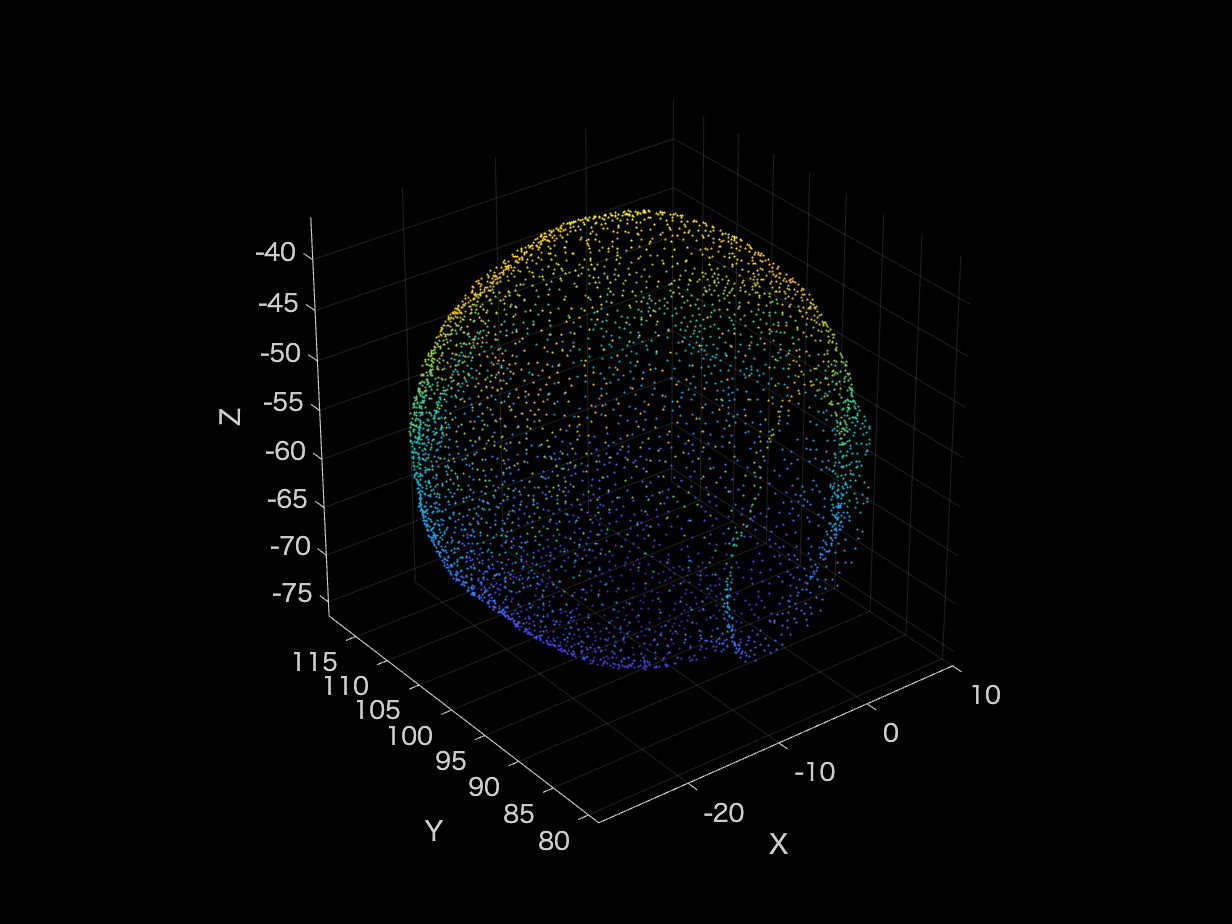

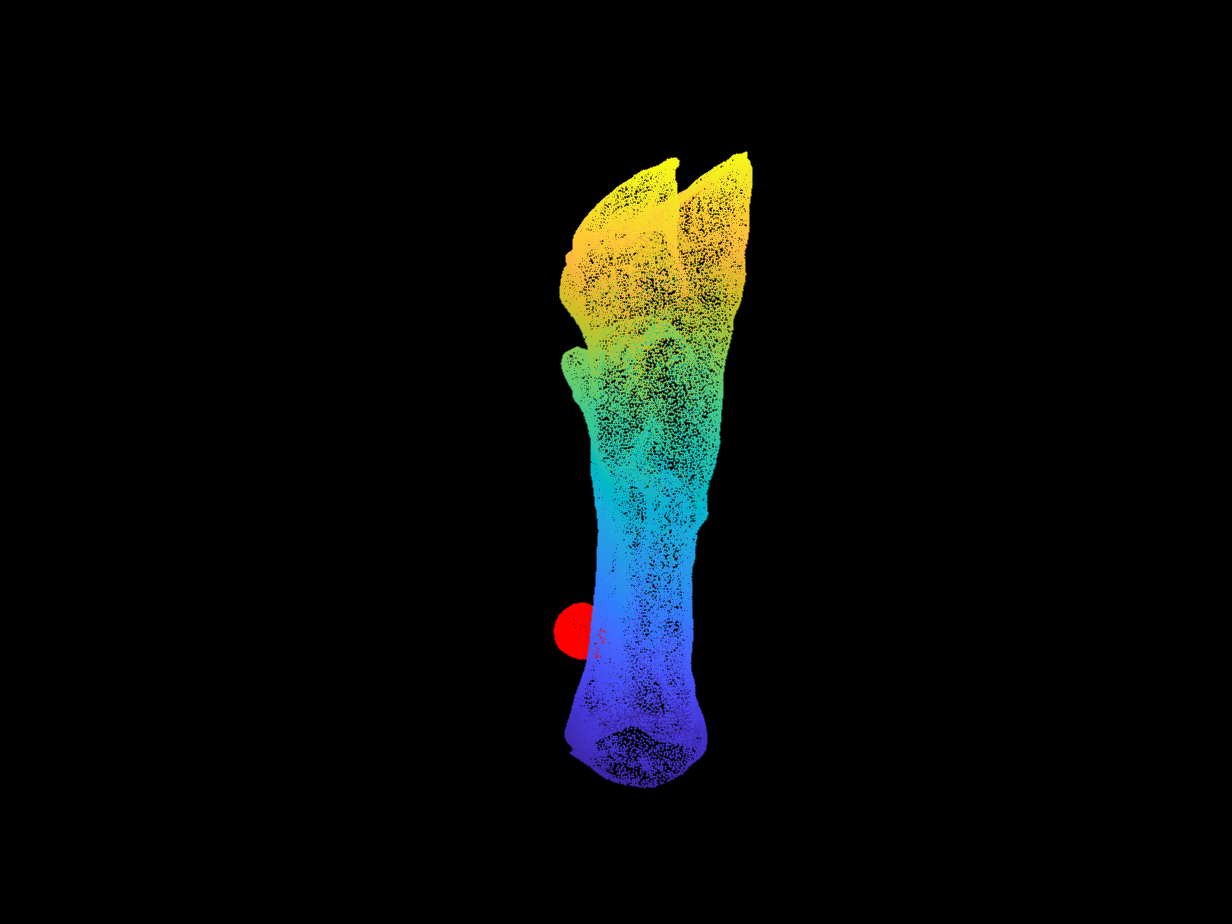

maxDist = 2;2

[model, inlierIn, out] = pcfitsphere(ptCloudWithMark, maxDist, 'MaxNumTrials',20000, 'SampleIndices',indices);
selSphere = select(ptCloudWithMark, inlierIn)
oSphere = select(ptCloudWithMark, out);
pcshowWithAxes(selSphere);
pcshow(ptCloudWithMark, "AxesVisibility","on");
hold on;             
pcshow(selSphere.Location, 'r');
hold off;

yli = selSphere.YLimits;
spt = selSphere.Location

spt =   -14.7971   80.1108  -58.9834
  -14.8679   79.5418  -59.3205
  -14.6117   79.7605  -58.9616
  -14.5075   80.3738  -53.9545
  -14.4302   80.2983  -55.4271
  -14.4472   79.7319  -54.6555
  -15.6441   78.9332  -57.7327
  -14.4514   79.6908  -55.3690
  -14.5340   79.7293  -56.2838
  -15.0144   79.2758  -55.9460


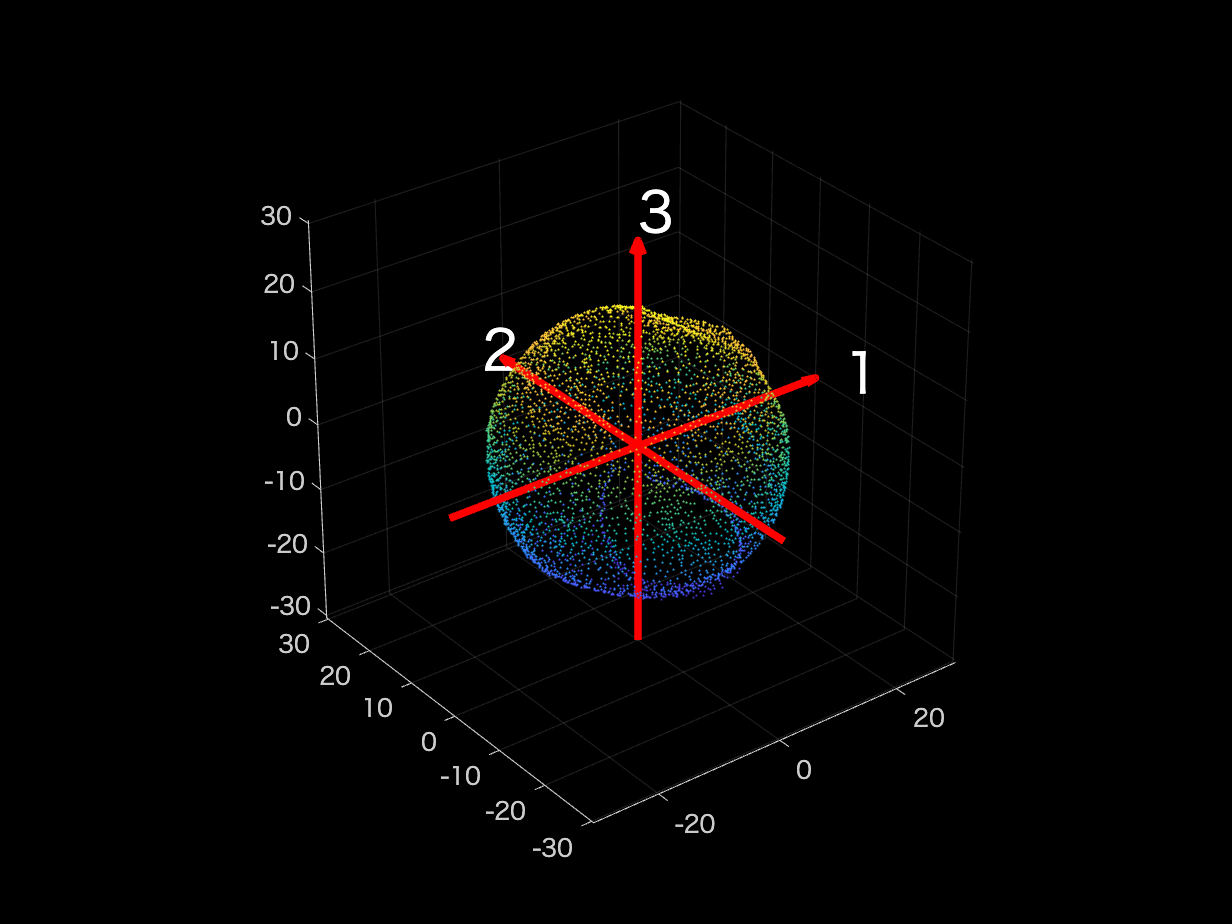

scoreandAxes(spt);

spt(:,2)

ans =    80.1108
   79.5418
   79.7605
   80.3738
   80.2983
   79.7319
   78.9332
   79.6908
   79.7293
   79.2758


cutspt = spt(spt(:,2)<=yli(2) & yli(1)+6 < spt(:,2),:);

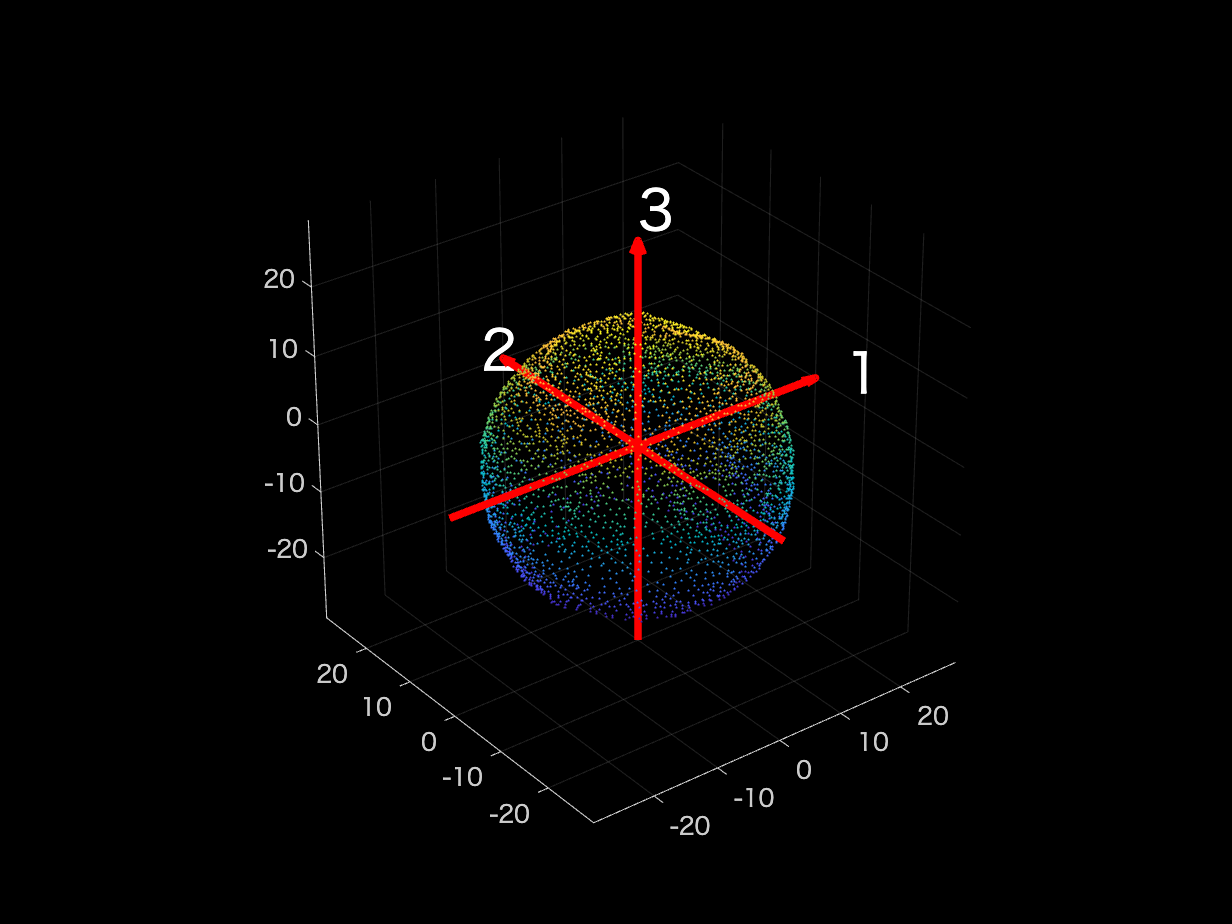

% pcshow(cutspt);
score = scoreandAxes(cutspt);

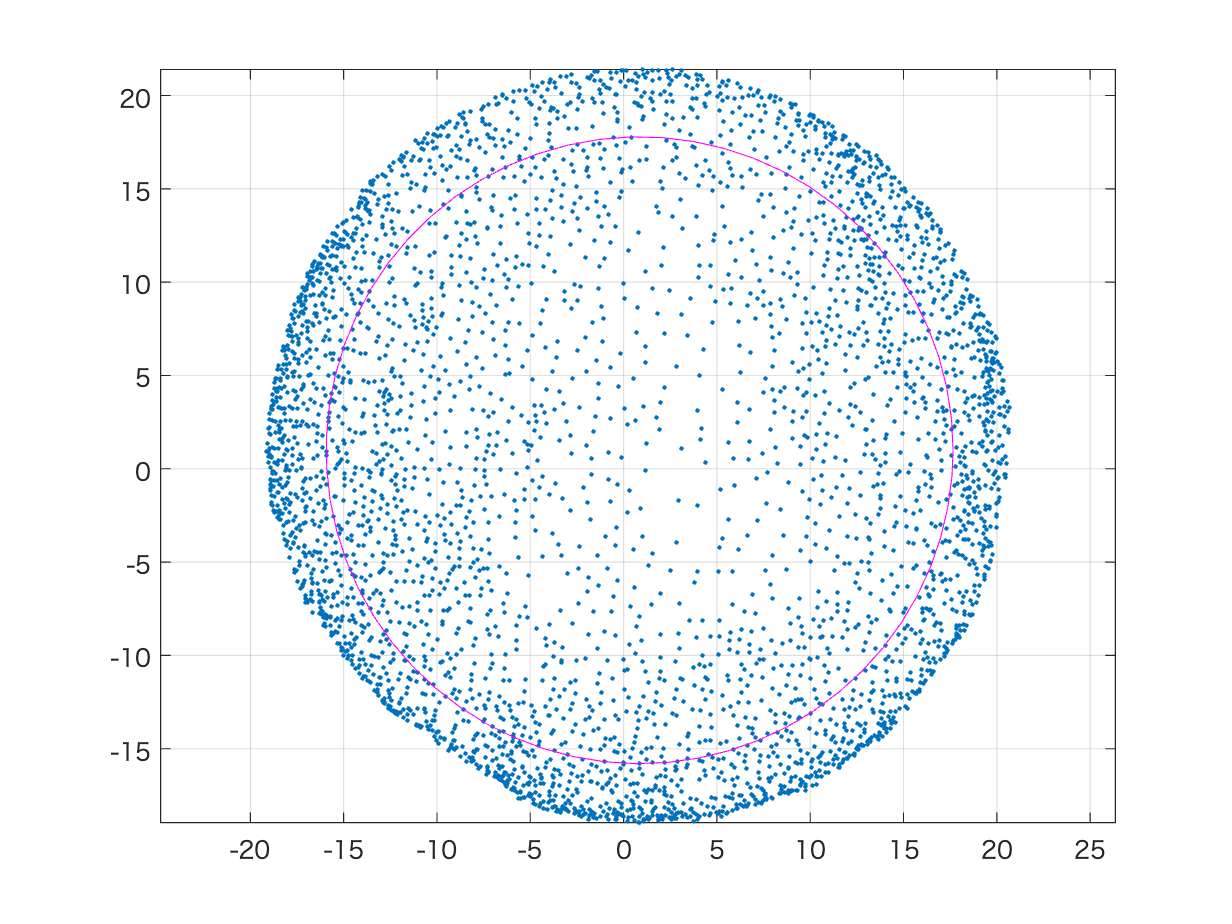

proJ = score(:,[1 2]);
figure();
x = proJ(:,1);
y = proJ(:,2);
plot(x, y, '.');

hold on;
grid on;
% 円近似
[cxe, cye, re] = CircleFitting(x, y);
theta=[0:0.1:2*pi 0];
xe=re*cos(theta)+cxe;
ye=re*sin(theta)+cye;
plot(xe,ye,'-m');hold on;
daspect([1 1 1]);
grid on;
axis equal;
hold off;

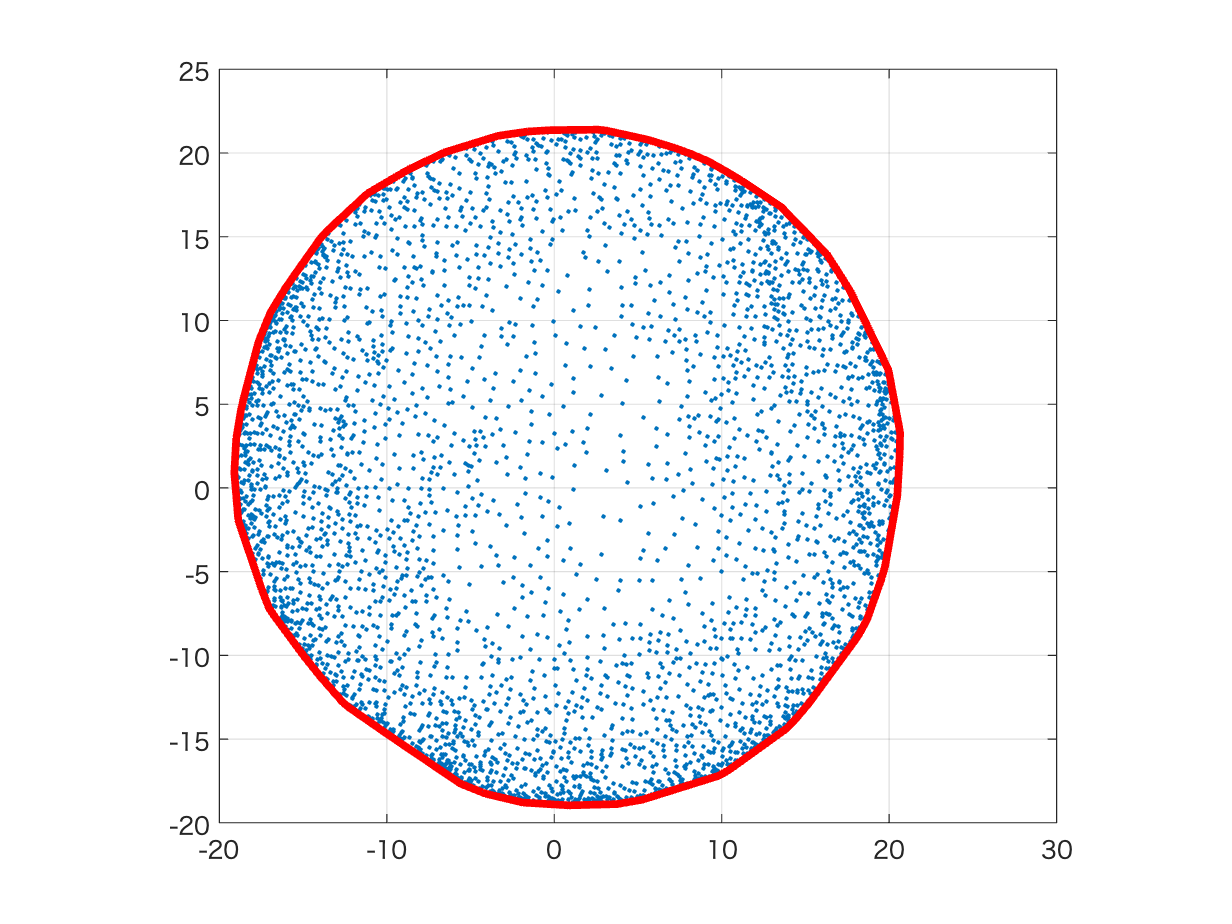

K = convhull(x, y);
kx = x(K); ky = y(K);
plot(x, y, '.');hold on;
grid on;
plot(kx,ky,'r', 'LineWidth',3.5);
daspect([1 1 1]);
hold off;

[cxk, cyk, rk] = CircleFitting(kx, ky);
cxk

cxk = 0.9405

cyk

cyk = 1.3012

rk

rk = 20.0090

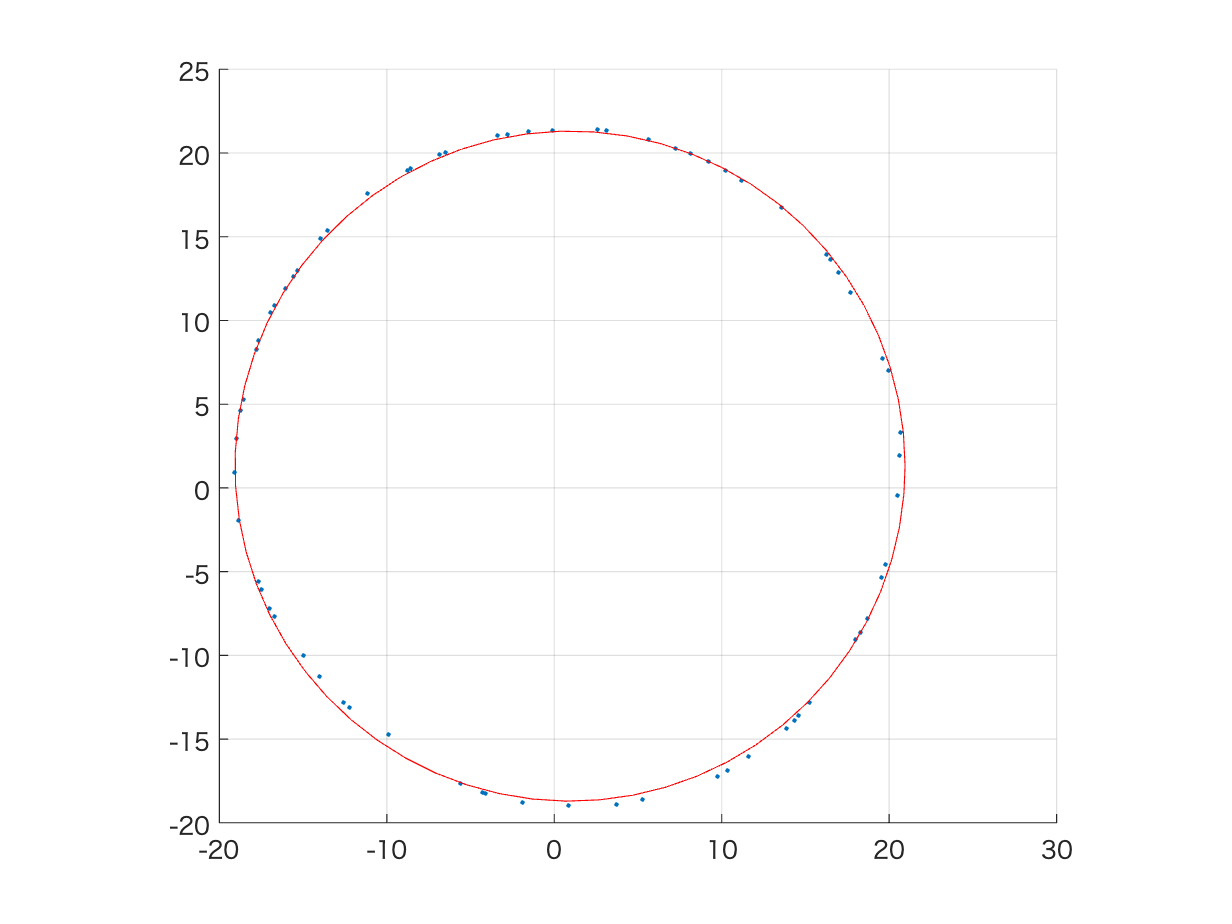

% theta=[0:0.1:2*pi 0];
x_k=rk*cos(theta)+cxk;
y_k=rk*sin(theta)+cyk;
figure();
hold on; grid on;
plot(kx, ky, '.');
daspect([1 1 1]);
plot(x_k, y_k, 'r');
hold off;

kpro = [kx ky];

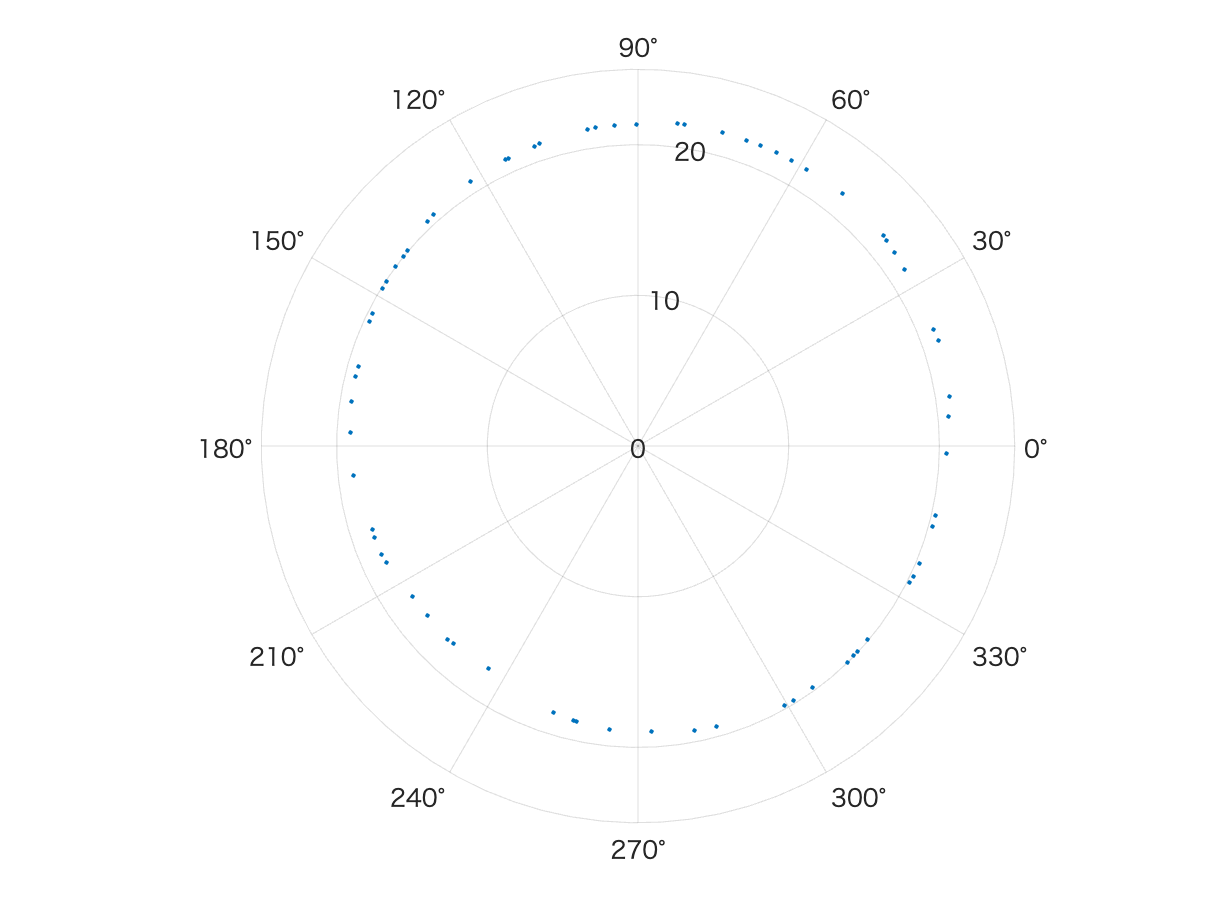

[thetaSorted, rhoSorted] = sortPointOnPolar(kpro);
figure()
polarplot(thetaSorted, rhoSorted, '.');

tfrom = [-cxk, -cyk, 0];
pt = pointCloud(score);
tfPoint = transform(pt, 0, 'x', tfrom);
tfp = tfPoint.Location

tfp =    11.3322   14.7221  -10.5416
   10.6001   15.4840  -10.0648
   10.4718   14.7724  -11.6129
    9.3725   15.5980  -11.2233
    9.5317   15.2628  -11.9647
    9.9146   14.5098  -12.6691
   10.6614   12.8316  -13.8532
    8.7042   15.5470  -12.2787
    7.9606   14.8496  -14.1509
    7.8059   15.9460  -12.6340


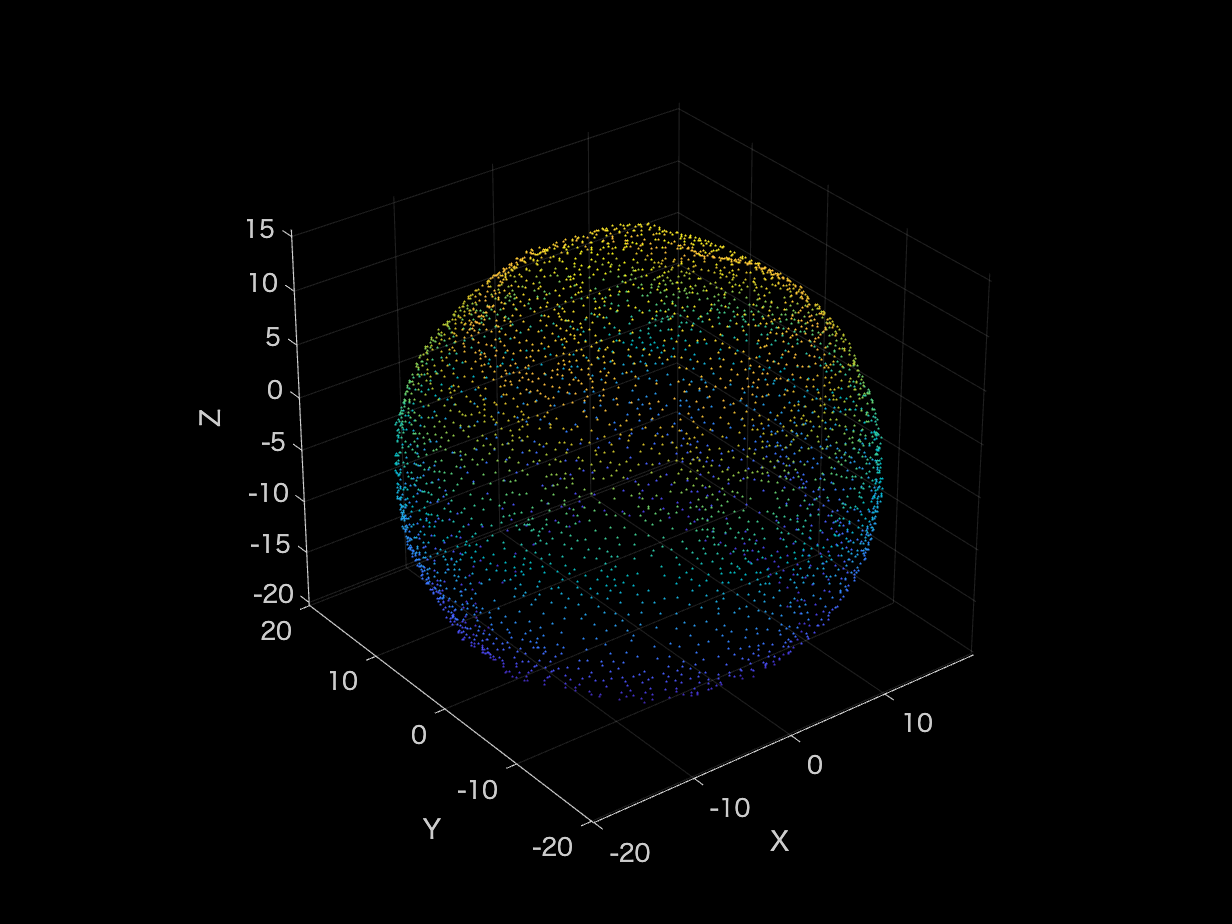

pcshowWithAxes(tfPoint);

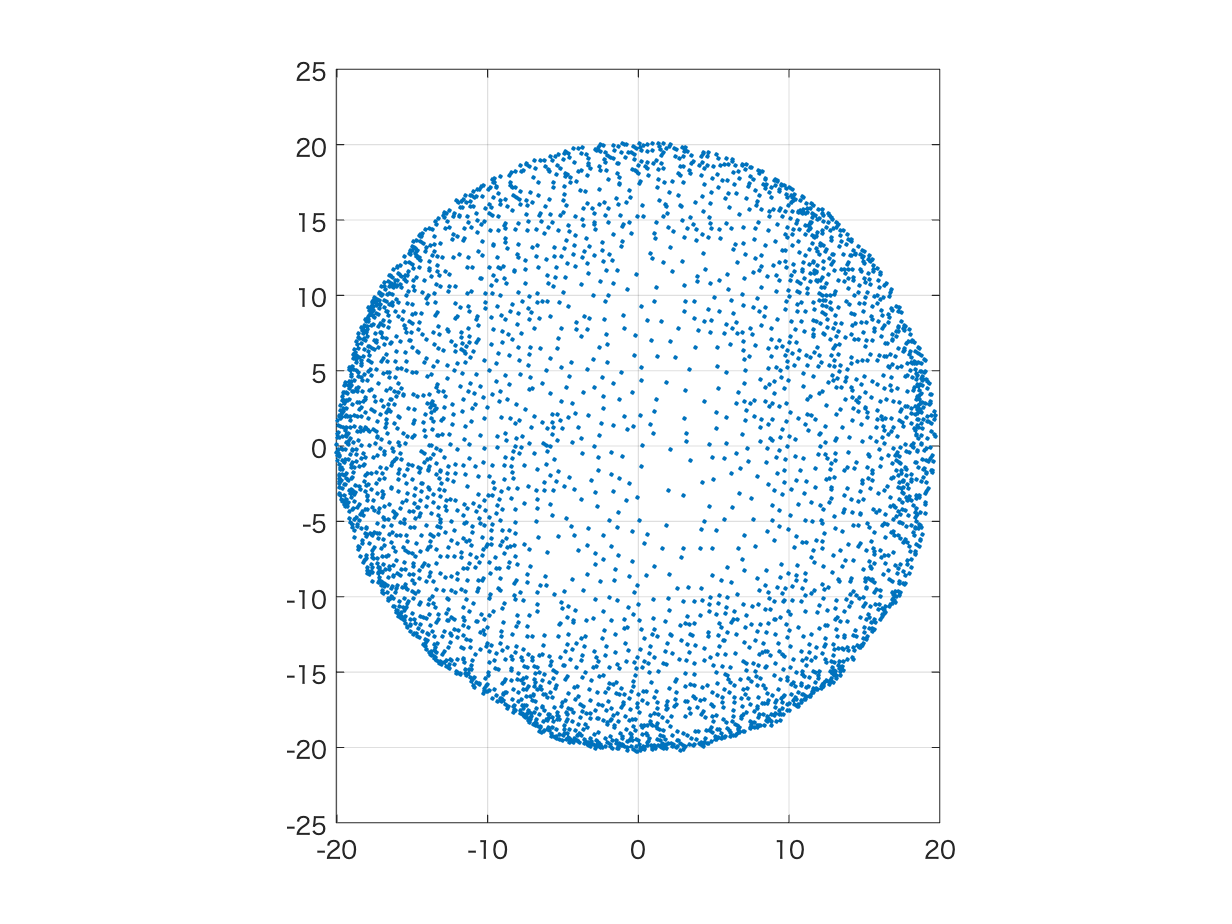


tfproJ = tfp(:, [1 2]);
tf_x = tfproJ(:,1);
tf_y = tfproJ(:,2);
figure;

plot(tf_x, tf_y, '.');
grid on;
daspect([1 1 1])

tfK = convhull(tf_x, tf_y);
tfkx = tf_x(tfK); tfky = tf_y(tfK);

tfproK = [tfkx tfky];
[tfx, tfy, tfr] = CircleFitting(tfkx, tfky);

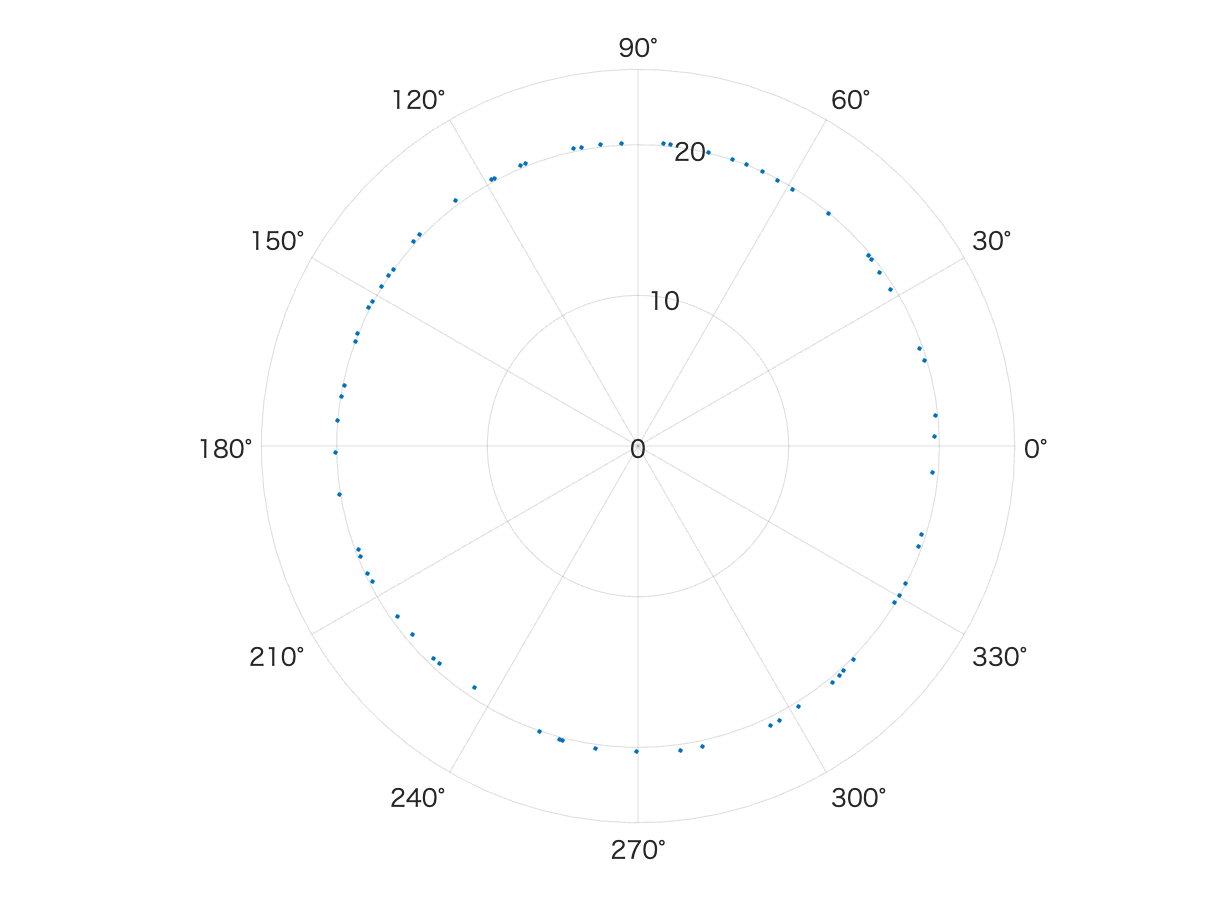

% 凸包で選んだ点群のソート
[tftheta, tfrho] = sortPointOnPolar(tfproK);
polarplot(tftheta, tfrho, '.');

max(tfrho)

ans = 20.5046

min(tfrho)

ans = 19.3707

ｘ軸，y軸方向の両端座標より半径算出

抽出個数が少ない

tx = tfPoint.XLimits;
ty = tfPoint.YLimits;
txlen = abs(tx(1))+abs(tx(2))

txlen = 39.7630

tylen = abs(ty(1))+abs(ty(2))

tylen = 40.3515

凸包で選ばれた点群の半径を二倍にして平均をとる

tfrho;
dia = tfrho*2;
rhomean = mean(dia)

rhomean = 40.0153

markersize = 40;
rate = rhomean / markersize

rate = 1.0004

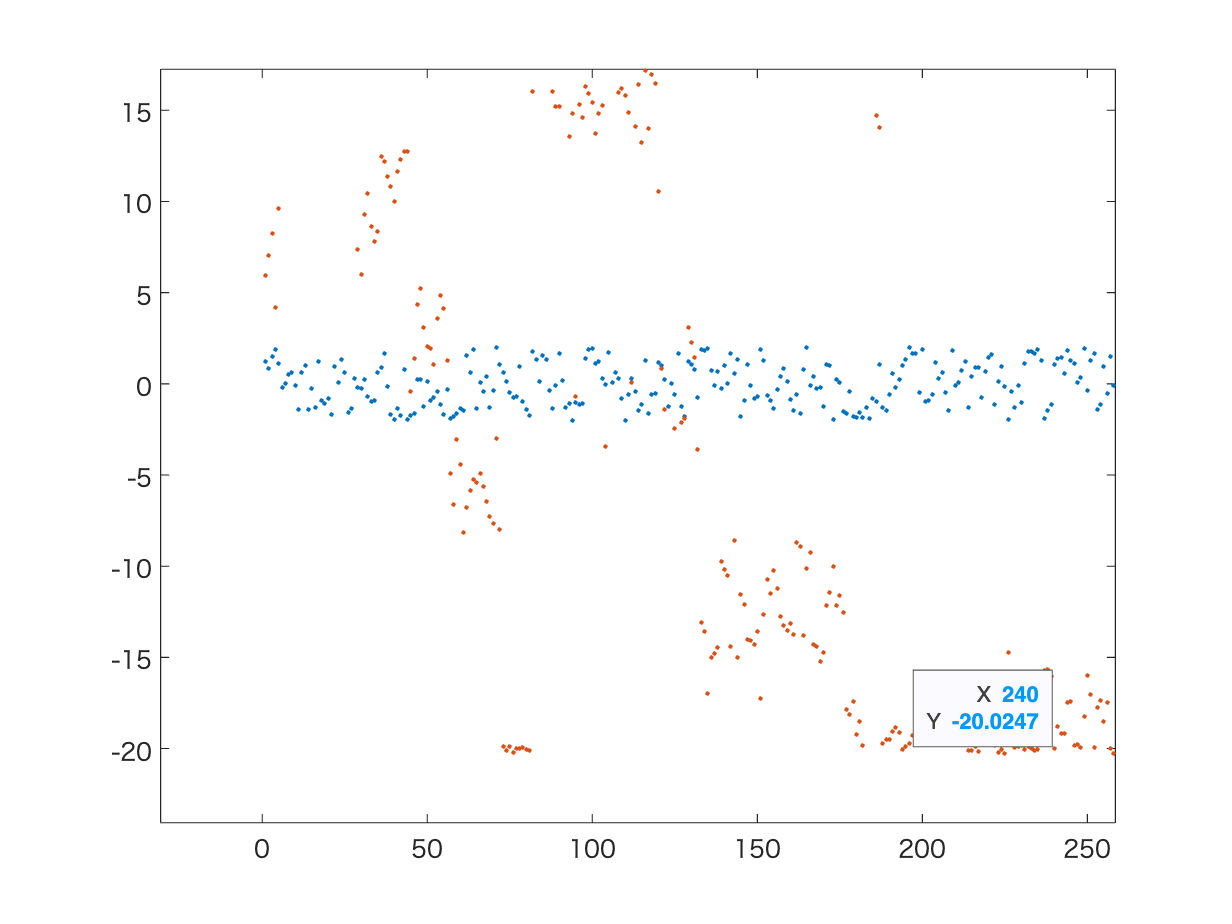

index  = tfproJ(:, 1) > -2 & 2 > tfproJ(: ,1);
tfproCut = tfproJ(index,:);
figure;
plot(tfproCut, '.')